## Bistable Trigger Model

Ferrell et al 2011 (Cell)


$$\frac{dCDK1}{dt} = \alpha_1 -\beta_1 * CDK1* \left[\frac{APC^{n1}}{K_1^{n1}+APC^{n1}}\right] + \alpha_3*(1-CDK1)*\frac{CDK1^{n3}}{K_3^{n3}+CDK^{n3}}\\

\frac{dAPC}{dt} = \alpha_2 * (1-APC)  * CDK1* \left[\frac{CDK1^{n2}}{K_2^{n2}+CDK1^{n2}}\right] - \beta_2 * APC $$


Parameters:

param_bt.a1 = 0.02;
param_bt.b1 = 3;
param_bt.K1 = 0.5;
param_bt.n1 = 8;
param_bt.a2 = 3;
param_bt.b2 = 1;
param_bt.K2 = 0.5;
param_bt.n2 = 8;
param_bt.a3 = 3;
param_bt.K3 = 0.5;
param_bt.n3 = 8;

Solve and Plot bistable trigger ODE:

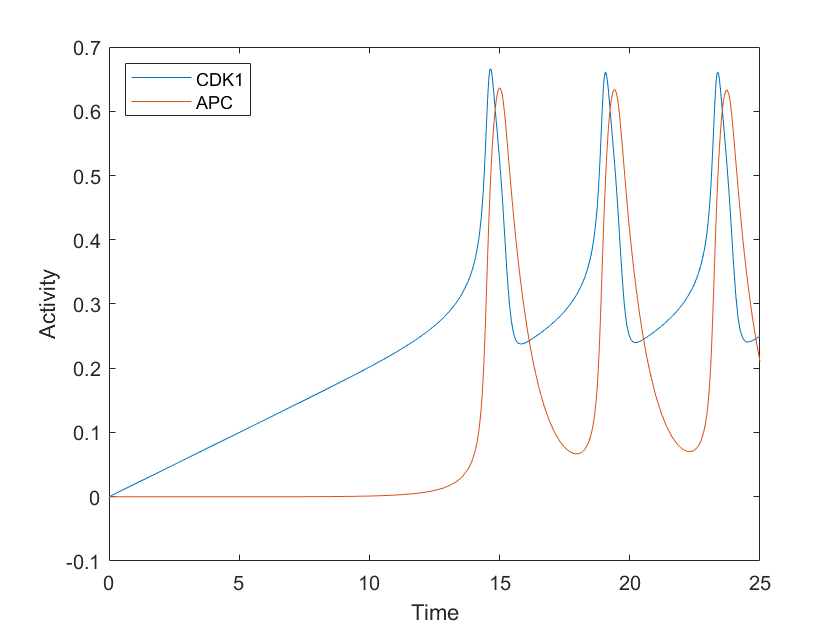

x0 = [0,0];
T0 = 0;
% initial time
Tf = 25;
% final time = 25
[tout,x] = ode45(@(t,y) differential_equation_bt(t,y,param_bt),[T0 Tf],x0);
% this function uses variable step sizes, but in general, we like uniform
% step sizes, so we interpolate the result here...
tpositions = 0:0.01:25;
xi = interp1(tout,x,tpositions);

figure;
zoom on;
plot(tpositions,xi);
ylabel('Activity');
xlabel('Time')
leg = legend('CDK1','APC');
leg.Location ='Northwest';

Plot the CDK1/APC Phase Space 

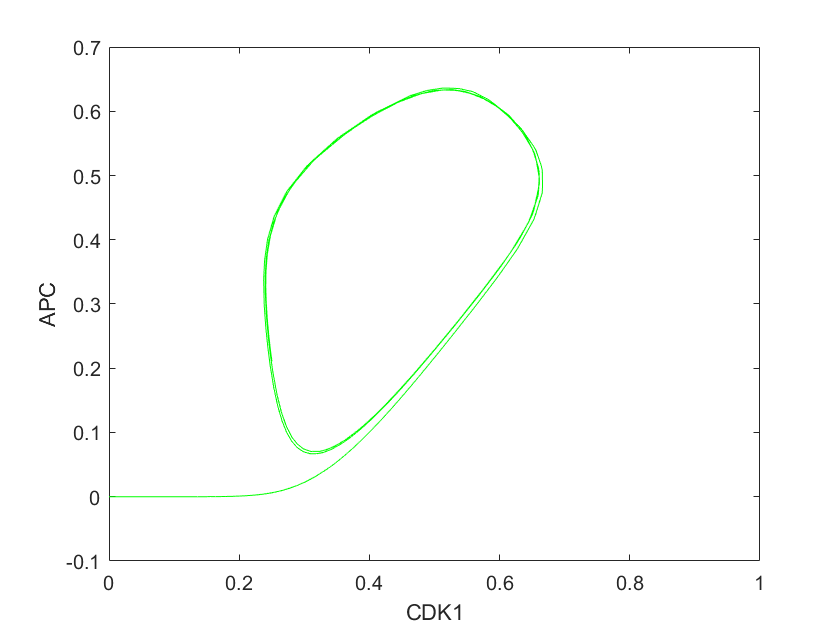

syms cdk apc
eqs1 = param_bt.a1 - param_bt.b1*cdk*apc^param_bt.n1/(param_bt.K1^param_bt.n1+apc^param_bt.n1) ...
+ param_bt.a3*(1-cdk)*cdk^param_bt.n3/(param_bt.K3^param_bt.n3+cdk^param_bt.n3) == 0;
eqs2 = param_bt.a2*(1-apc)*cdk^param_bt.n2/(param_bt.K2^param_bt.n2+cdk^param_bt.n2) - param_bt.b2*apc == 0;
cdk_null = vpasolve(eqs1, cdk); % function of apc
apc_null = vpasolve(eqs2, apc); % function of cdk
%}

figure;
zoom on; box on;
hold on;
%plot(tout,x,'r.'); %unequally time-spaced points. Plotting every point
plot(xi(:,1),xi(:,2),'g');
%equally time spaced points
%plot(subs(cdk_null,apc,xi(2:end,2)),xi(2:end,2),'b')
%plot(xi(2:end,1),subs(apc_null,cdk,xi(2:end,1)),'r')
xlim([0,1])
ylabel('APC');
xlabel('CDK1');

Bistable Trigger system of equations:

function dydt_bt = differential_equation_bt(t,y,p)
    dydt_bt = zeros(2,1);
    dydt_bt(1) = p.a1 - p.b1*y(1)*y(2)^p.n1/(p.K1^p.n1+y(2)^p.n1) + p.a3*(1-y(1))*y(1)^p.n3/(p.K3^p.n3+y(1)^p.n3);
    dydt_bt(2) = p.a2*(1-y(2))*y(1)^p.n2/(p.K2^p.n2+y(1)^p.n2) - p.b2*y(2);
end